# ** Displacement1 **

# **=====================================================================================**

**_D** means displacement 1; **_E** means displacement 2

# **Step 1: Construct PCE**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



global myPCE_D S_D V_D number_D st_D mv_D myPCE_E S_E V_E number_E st_E mv_E

## 2 - ABAQUS FE realization ${\mathcal{M}}(r)$-- Part one: Displacement1

read input and output

Xsample  =  xlsread('Input.csv');
Truss_D = xlsread('D_output.csv','Stage1');

%catenate X and Deflection1
FE_D = [ Xsample Truss_D];
size(FE_D)

ans =     29     3


%get the number of priors
N_prior  =  size(Xsample,2);

## 3 - PCE1 for deflection1

Tell output whether an empty


if ~isempty(Truss_D)


Note: priors for PCE input, not for Bayesian inference prior input

prior for PCE input

    
    for i = 1: N_prior
        InputOpts_D.Marginals(i).Type = 'Uniform';
        minD = min(Xsample(:,i));
        maxD = max(Xsample(:,i));
        InputOpts_D.Marginals(i).Parameters  = [minD maxD];
    end

    
    myInput = uq_createInput(InputOpts_D);

## 4 PCA for PCE1

    %get the FE output
    PCA_N_D = 1;
    
    Y_Output = Truss_D;
    size(Y_Output)

ans =     29     1


PCA reduction 

    [V_D,S_D,E_D,cumE_D,number_D]=princa(Y_Output,0.99);
    number_D = PCA_N_D;
    [m, n] = size(S_D);  % Gets the dimensions of S
    mv_D = mean(Y_Output);  % The mean of the raw data
    st_D = std(Y_Output);   % Standard deviation of the original data
    

## 5 - PCE1

    metaopts.Type = 'Metamodel';
    metaopts.MetaType = 'PCE';
    metaopts.Method = 'LARS';
    metaopts.TruncOptions.qNorm = 0.75;
    metaopts.Degree = 2:15;

Experimental design (Note: PCE on Pricinple component of Y outputs, not on Y outputs)

    X = Xsample(:,1:N_prior);
    size(X)

ans =     29     2


    Y = S_D(:, 1:number_D);
    size(Y)

ans =     29     1


    metaopts.ExpDesign.X = X;
    metaopts.ExpDesign.Y = Y;

Calculation

    myPCE_D = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 5.025623e-06
---                 Calculation finished!                               ---


## Sobol's indices

Select the metamodeling tool in UQLab and the polynomial chaos expansion (PCE) type:

    SobolOpts.Type = 'Sensitivity';
    SobolOpts.Method = 'Sobol';

Specify the maximum order of the Sobol' indices to be calculated:

    SobolOpts.Sobol.Order = 1;

Run the sensitivity analysis:

    mySobolAnalysisPCE = uq_createAnalysis(SobolOpts);


Starting Sobol' indices analysis...

Calculating PCE-based Sobol' indices up to order 1


    uq_print(mySobolAnalysisPCE)

--------------------------------------------------
     Total Sobol' indices for output component 1
--------------------------------------------------
X1          X2          
0.000002    0.999998    
--------------------------------------------------
--------------------------------------------------
    First Order Sobol' indices for output component 1
--------------------------------------------------
X1          X2          
0.000002    0.999998    
--------------------------------------------------
Total cost (model evaluations): 0



## 6 - Yval1 vs YPCE1

Create a validation sample of size  from the input model:

    Xval =  FE_D(:,1:N_prior);
    size(Xval)

ans =     29     2


Evaluate the full model response at the validation sample points:

    Yval =  Truss_D;
    size(Yval)

ans =     29     1


Responses for PCE 

    % Obtain the principle components of Y output
    YPCE= uq_evalModel(myPCE_D,Xval);
    
    % %reconstruct the output
    
    YPCE = S_D(:, 1:number_D) * V_D(:, 1:number_D)';
    % De-normalize the score for each principal component
    for i = 1:size(YPCE, 2)
        YPCE(:, i) = YPCE(:, i) * st_D(i) + mv_D(i);
    end
    

True vs predicted plot (Note: plot on the full order Y output, not on the PCs)

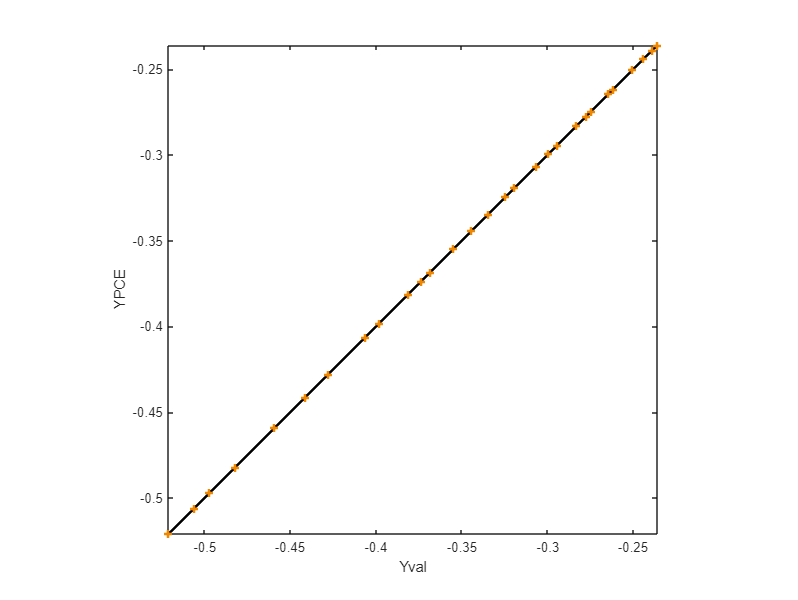

    close all;
    uq_figure
    
    hold on
    uq_plot([min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')], 'k')
    
    axis equal
    axis([[min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')]])
    uq_plot(Yval, YPCE, '+')
    xlabel('Yval');
    ylabel('YPCE');
    box on;
    hold off;




end

## 7 - ABAQUS FE realization ${\mathcal{M}}(r)$-- Part two: Deflection2

**_D** means deflection1; **_E** means deflection2

Truss_E = xlsread('E_output.csv','Stage1');

%catenate X and Deflection2
FE_E = [ Xsample Truss_E];
size(FE_E)

ans =     29     2


## 8 - PCE2 for Deflection2

Note: priors for PCE input, not for Bayesian inference prior input

tell output whether empty

if ~isempty(Truss_E)

    
    for i = 1: N_prior
        InputOpts_E.Marginals(i).Type = 'Uniform';
        minE = min(Xsample(:,i));
        maxE = max(Xsample(:,i));
        InputOpts_E.Marginals(i).Parameters  = [minE maxE];
    end
    
    
    myInput = uq_createInput(InputOpts_E);

## 9 PCA for PCE2

    %get the FE output
    PCA_N_E = 1;
    
    Y_Output = Truss_E;
    size(Y_Output)

PCA reduction 

    [V_E,S_E,E_E,cumE_E,number_E]=princa(Y_Output,0.99);
    number_E = PCA_N_E;
    [m, n] = size(S_E);  % Gets the dimensions of S
    mv_E = mean(Y_Output);  % The mean of the raw data
    st_E = std(Y_Output);   % Standard deviation of the original data
    

## 10 - PCE2

    metaopts.Type = 'Metamodel';
    metaopts.MetaType = 'PCE';
    metaopts.Method = 'LARS';
    metaopts.TruncOptions.qNorm = 0.75;
    metaopts.Degree = 2:15;

Experimental design (Note: PCE on Pricinple component of Y outputs, not on Y outputs)

    X = Xsample(:,1:N_prior);
    size(X)
    Y = S_E(:, 1:number_E);
    size(Y)
    metaopts.ExpDesign.X = X;
    metaopts.ExpDesign.Y = Y;

Calculation

    myPCE_E = uq_createModel(metaopts);

## Sobol's indices

Select the metamodeling tool in UQLab and the polynomial chaos expansion (PCE) type:

    SobolOpts.Type = 'Sensitivity';
    SobolOpts.Method = 'Sobol';

Specify the maximum order of the Sobol' indices to be calculated:

    SobolOpts.Sobol.Order = 1;

Run the sensitivity analysis:

    mySobolAnalysisPCE = uq_createAnalysis(SobolOpts);
    uq_print(mySobolAnalysisPCE)

## 11 - Yval2 vs YPCE2

Create a validation sample of size  from the input model:

    Xval =  FE_E(:,1:N_prior);
    size(Xval)

Evaluate the full model response at the validation sample points:

    Yval =  Truss_E;
    size(Yval)

Responses for PCE 

    % Obtain the principle components of Y output
    YPCE= uq_evalModel(myPCE_E,Xval);
    
    % %reconstruct the output
    
    YPCE = S_E(:, 1:number_E) * V_E(:, 1:number_E)';
    % De-normalize the score for each principal component
    for i = 1:size(YPCE, 2)
        YPCE(:, i) = YPCE(:, i) * st_E(i) + mv_E(i);
    end
    

True vs predicted plot (Note: plot on the full order Y output, not on the PCs)

    close all;
    uq_figure
    
    hold on
    uq_plot([min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')], 'k')
    
    axis equal
    axis([[min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')]])
    uq_plot(Yval, YPCE, '+')
    xlabel('Yval');
    ylabel('YPCE');
    box on;
    hold off;

end

# **Step 2: Bayesian inversion-initial stage one **

## 1 - Define the Measurement 

Ground truth:


$$X1: 1.078495977	\\
X2: 1.983330298  \\
$$


Measurement for deflection 1

tell whether measurement is empty

%define a very small value
epsilon  = 1e-20;

Measurement_D = xlsread('D_observation.csv','Stage1');

%Add noise
noisePerc = 0.0;

if ~isempty(Measurement_D)    
    
    Sigmas = noisePerc *Measurement_D
    
    randomNoise = normrnd(0,1, [1 size(Measurement_D,2)])
    
    randomNoiseAll = randomNoise .* Sigmas ;
    
    Measurement_D = Measurement_D + randomNoiseAll ;
    size(Measurement_D)
else
    Measurement_D = epsilon;
end

Sigmas = 0

randomNoise = 0.1609

ans =      1     1


Measurement for deflection 2

Measurement_E = xlsread('E_observation.csv','Stage4');
%Add noise


if ~isempty(Measurement_E)
    Sigmas = noisePerc *Measurement_E
    
    randomNoise = normrnd(0,1, [1 size(Measurement_E,2)])
    
    randomNoiseAll = randomNoise .* Sigmas ;
    
    Measurement_E = Measurement_E + randomNoiseAll ;
    
    size(Measurement_E)
else
    Measurement_E = epsilon;
end

catenate measurement 

Measurement_All = [Measurement_D Measurement_E];
size(Measurement_All)

ans =      1     2


## 2 - Define the priors 


%Probabilistic input parameters
Input_Name    =   {'A1',      'A2'};  
parameter1      =   [1.0 1.8 ];
parameter2      =   [2.0 2.5 ]; 
type =              ["uniform",  "uniform"];

%Number of variables: N_input
N_input = length(Input_Name);

% Create the INPUT object
PriorOpts = DataInput(Input_Name, parameter1, parameter2, type); 

%Priors on sigma2_1
if ~isempty(Truss_D)
    N_input = N_input + 1;
    scale_discrepancy1 = 0.1;
    PriorOpts.Marginals(N_input).Name = 'Sigma2_1';               % sigma2
    PriorOpts.Marginals(N_input).Type = 'Uniform';
    sigma2_1 = mean(Measurement_D(:,:),"all").*scale_discrepancy1;
    PriorOpts.Marginals(N_input).Parameters  = [0 sigma2_1.^2];
    PriorOpts.Marginals(N_input).Bounds  = [0 inf];
end

%Priors on sigma2_2
if ~isempty(Truss_E)
    N_input = N_input + 1;
    scale_discrepancy2 = 0.1;
    PriorOpts.Marginals(N_input).Name = 'Sigma2_1';               % sigma2
    PriorOpts.Marginals(N_input).Type = 'Uniform';
    sigma2_2 = mean(Measurement_E(:,:),"all").*scale_discrepancy2;
    PriorOpts.Marginals(N_input).Parameters  = [0 sigma2_2.^2];
    PriorOpts.Marginals(N_input).Bounds  = [0 inf];
end

myPriorDist = uq_createInput(PriorOpts);






%Get prior sampling with excavation stage from distribution


N_Prior_Sample = 1000;
Prior_sample = uq_getSample(N_Prior_Sample,'LHS');
Prior_sample_Sum = {};
Prior_sample_Sum{1} = Prior_sample(:,1:N_prior);


## 3 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$


myData.y = Measurement_All;
size(myData.y)

ans =      1     2


myData.Name = 'Deflection1 and Deflection2';

Loglikelihood still follows the Gaussian discrepancy criteria

if ~isempty(Truss_D) & ~isempty(Truss_E) 
    myLogLikeli = @(params,y) LL1(params,y(:,1)) + LL2(params,y(:,2));
elseif  ~isempty(Truss_D) & isempty(Truss_E) 
    myLogLikeli = @(params,y) LL1(params,y(:,1));
elseif  isempty(Truss_D) & ~isempty(Truss_E) 
    myLogLikeli = @(params,y) LL2(params,y(:,2));    
end


## 5 - Solver options

Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = 1:N_prior;
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 800;
Solver.MCMC.NChains = 30;


## 5 - Bayesian inference


Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

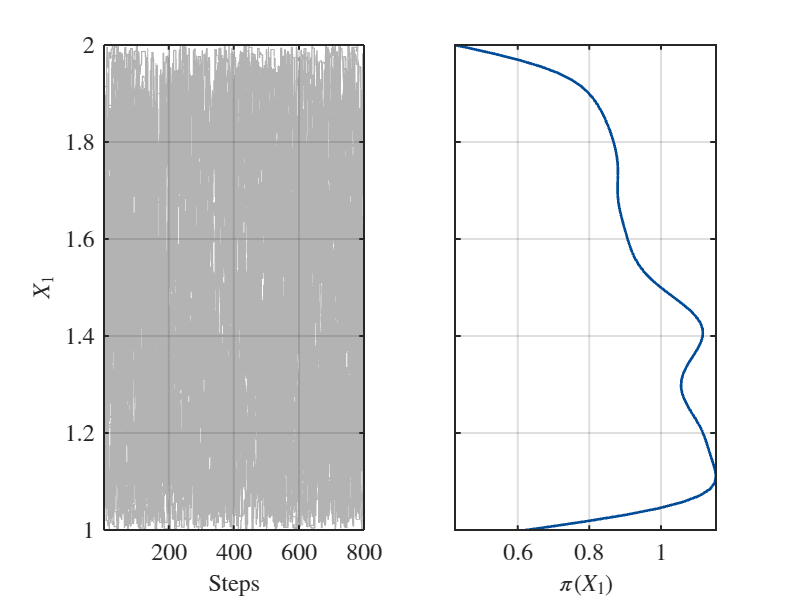

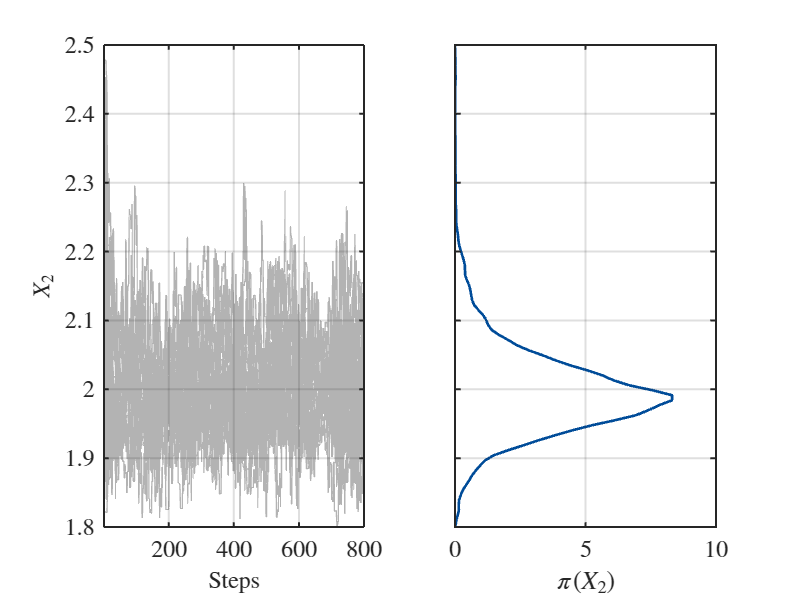


Finished AIES!


BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

## 11 - Post-processing

Burn in 70%; 


uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7);

uq_print(BayesAnalysis);

%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:15
   Number of sample points:                       2.40e+04

%------------------- Posterior Marginals
--------------------------------------------------------------
| Parameter | Mean    | Std     | (0.05-0.95) Quant. | Type  |
--------------------------------------------------------------
| A1        | 1.5     | 0.29    | ( 1 - 1.9)         | Model |
| A2        | 2       | 0.061   | (1.9 - 2.1)        | Model |
| Sigma2_1  | 0.00096 | 0.00048 | (0.00014 - 0.0017) | Model |
--------------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | MAP     | Parameter Type |
---------------------------------------

% create cell to store the variables X1-X10
%%Note: dont use eval function (too redundent)
X_New_sample = {};
%extract samples from the posterior 
for i = 1: N_prior

    X_Postsample =  BayesAnalysis.Results.PostProc.PostSample(:,i,:);
    X_New_sample{i} = reshape(permute(X_Postsample, [2 1 3]), size(X_Postsample, 2), [])';

end
X_New_sample = cell2mat(X_New_sample);
% get mean and std of X1-X10 posterior
% create cell to store the mean and std of X1-X10
Mean_X = {};
Std_X = {};
for k = 1: N_prior
    Mean_X{k} = BayesAnalysis.Results.PostProc.Percentiles.Mean(:,k);
    Std_X{k} = BayesAnalysis.Results.PostProc.Percentiles.Var(:,k)^0.5;
end

% convert cell Mean_X/Std_X into matrix
Matrix_Mean_X = cell2mat(Mean_X)';
Matrix_Std_X = cell2mat(Std_X)';
Mean_Std_Sum{1} = [Matrix_Mean_X Matrix_Std_X];



# **Step 3: Sequential Bayesian inversion-starting from stage two **

[~,sheets,~] = xlsfinfo('D_output.csv');
N_Stage = numel(sheets);

for itotal = 2:N_Stage

##  PCA-PCE for deflection 1

    %tell output whether empty
    Truss_D = xlsread('D_output.csv',['Stage',num2str(itotal)]);
    if ~isempty(Truss_D)
        
        
        %PCE priors  for deflection 1
        for ii = 1: N_prior
            InputOpts_D.Marginals(ii).Type = 'Uniform';
            minD = min(Xsample(:,ii));
            maxD = max(Xsample(:,ii));
            InputOpts_D.Marginals(ii).Parameters  = [minD maxD];
        end
        myInput = uq_createInput(InputOpts_D);
    
    
    
        %PCA  

        Y_Output = Truss_D;
        size(Y_Output)
        [V_D,S_D,E_D,cumE_D,number_D]=princa(Y_Output,0.99);
        number_D = PCA_N_D;
        [m, n] = size(S_D);  % Gets the dimensions of S
        mv_D = mean(Y_Output);  % The mean of the raw data
        st_D = std(Y_Output);   % Standard deviation of the original data
    
        %PCE surrogate for deflection1
        metaopts.Type = 'Metamodel';
        metaopts.MetaType = 'PCE';
        metaopts.Method = 'LARS';
        metaopts.Degree = 2:15;
        X = Xsample(:,1:N_prior);
        Y = S_D(:, 1:number_D);
        metaopts.ExpDesign.X = X;
        metaopts.ExpDesign.Y = Y;
        myPCE_D = uq_createModel(metaopts); 
    end

    %measurement + noise
    Measurement_D = xlsread('D_observation.csv',['Stage',num2str(itotal)]);


    if ~isempty(Measurement_D) 
        Sigmas = noisePerc *Measurement_D;
        randomNoise = normrnd(0,1, [1 size(Measurement_D,2)])
        randomNoiseAll = randomNoise .* Sigmas ;
        Measurement_D = Measurement_D + randomNoiseAll ;
    else
        Measurement_D = epsilon;
    end


## PCA-PCE for deflection 2

    %PCE priors  for deflection 2
    Truss_E = xlsread('E_output.csv',['Stage',num2str(itotal)]);
    if ~isempty(Truss_E)

        for ii = 1: N_prior
            InputOpts_E.Marginals(ii).Type = 'Uniform';
            minE = min(Xsample(:,ii));
            maxE = max(Xsample(:,ii));
            InputOpts_E.Marginals(ii).Parameters  = [minE maxE];
        end
        myInput = uq_createInput(InputOpts_E);
    
    
    
        %PCA  
        
        Y_Output = Truss_E;
        size(Y_Output)
        [V_E,S_E,E_E,cumE_E,number_E]=princa(Y_Output,0.99);
        number_E = PCA_N_E;
        [m, n] = size(S_E);  % Gets the dimensions of S
        mv_E = mean(Y_Output);  % The mean of the raw data
        st_E = std(Y_Output);   % Standard deviation of the original data
    
        %PCE surrogate for deflection1
        metaopts.Type = 'Metamodel';
        metaopts.MetaType = 'PCE';
        metaopts.Method = 'LARS';
        metaopts.Degree = 2:15;
        X = Xsample(:,1:N_prior);
        Y = S_E(:, 1:number_E);
        metaopts.ExpDesign.X = X;
        metaopts.ExpDesign.Y = Y;
        myPCE_E = uq_createModel(metaopts); 
    end

    %measurement + noise
    Measurement_E = xlsread('E_observation.csv',['Stage',num2str(itotal)]);

    if ~isempty(Measurement_E)
        
        Sigmas = noisePerc *Measurement_E;
        randomNoise = normrnd(0,1, [1 size(Measurement_E,2)])
        randomNoiseAll = randomNoise .* Sigmas ;
        Measurement_E = Measurement_E + randomNoiseAll ;
    else
        Measurement_E = epsilon;
    end


## Catenate measurement

    Measurement_All = [Measurement_D Measurement_E];
    size(Measurement_All)

## INFERENCE OF MARGINALS AND COPULA from last stage

    % infer priors for X1-X10
    iOpts.Inference.Data = X_New_sample;
    size(X_New_sample)
    iOpts.Name = ['InputX' num2str(itotal)];

    %Number of variables: N_input
    N_input = size(X_New_sample,2);

    %Priors on sigma2_1
    if ~isempty(Truss_D)
        N_input = N_input + 1;
        iOpts.Marginals(N_input).Name = 'Sigma2_1';               % sigma2
        iOpts.Marginals(N_input).Type = 'Uniform';
        sigma2_1 = mean(Measurement_D(:,:),"all").*scale_discrepancy1;
        iOpts.Marginals(N_input).Parameters  = [0 sigma2_1.^2];
        iOpts.Marginals(N_input).Bounds  = [0 inf];
    end
    
    %Priors on sigma2_2
    if ~isempty(Truss_E)
        N_input = N_input + 1;
        iOpts.Marginals(N_input).Name = 'Sigma2_1';               % sigma2
        iOpts.Marginals(N_input).Type = 'Uniform';
        sigma2_2 = mean(Measurement_E(:,:),"all").*scale_discrepancy2;
        iOpts.Marginals(N_input).Parameters  = [0 sigma2_2.^2];
        iOpts.Marginals(N_input).Bounds  = [0 inf];
    end   


    InputHat = uq_createInput(iOpts);


    %Get prior sampling with stages from distribution 
    Prior_sample = uq_getSample(N_Prior_Sample,'LHS'); 
    Prior_sample_Sum{itotal} = Prior_sample(:,1:N_prior);

## Custom loglikelihood and Bayesian inference

    %log likelihood
    myData.y = Measurement_All;
    size(myData.y)
    myData.Name = 'Deflection1 and Deflection2';

    % choose loglikelihood form

    if ~isempty(Truss_D) & ~isempty(Truss_E) 
        myLogLikeli = @(params,y) LL1(params,y(:,1)) + LL2(params,y(:,2));
    elseif  ~isempty(Truss_D) & isempty(Truss_E) 
        myLogLikeli = @(params,y) LL1(params,y(:,1));
    elseif  isempty(Truss_D) & ~isempty(Truss_E) 
        myLogLikeli = @(params,y) LL2(params,y(:,2));    
    end

    %Solver options

    Solver.Type = 'MCMC';
    Solver.MCMC.Visualize.Parameters = 1:N_prior;
    Solver.MCMC.Visualize.Interval = 10;
    Solver.MCMC.Sampler = 'AIES';
    Solver.MCMC.Steps = 800;
    Solver.MCMC.NChains = 30;

    %Bayesian inference
    BayesOpts.LogLikelihood = myLogLikeli;
    BayesOpts.Data = myData;
    BayesOpts.Type = 'inversion';
    BayesOpts.Solver = Solver;
    BayesOpts.Prior = InputHat;
    BayesAnalysis = uq_createAnalysis(BayesOpts);    
    

## Post - process

ans =     29     1


---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 1.842648e-05
---                 Calculation finished!                               ---


randomNoise = -1.9766

ans =      1     2


ans =         7200           2


ans =      1     2



Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

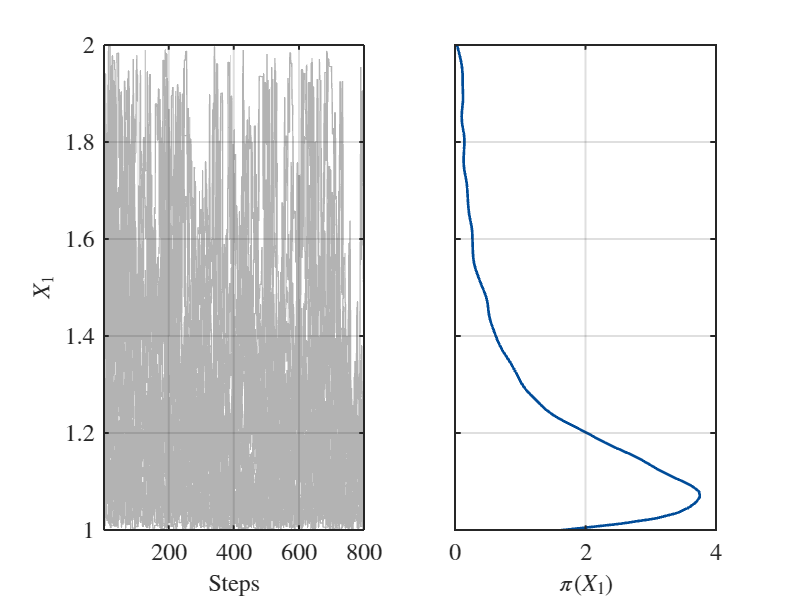

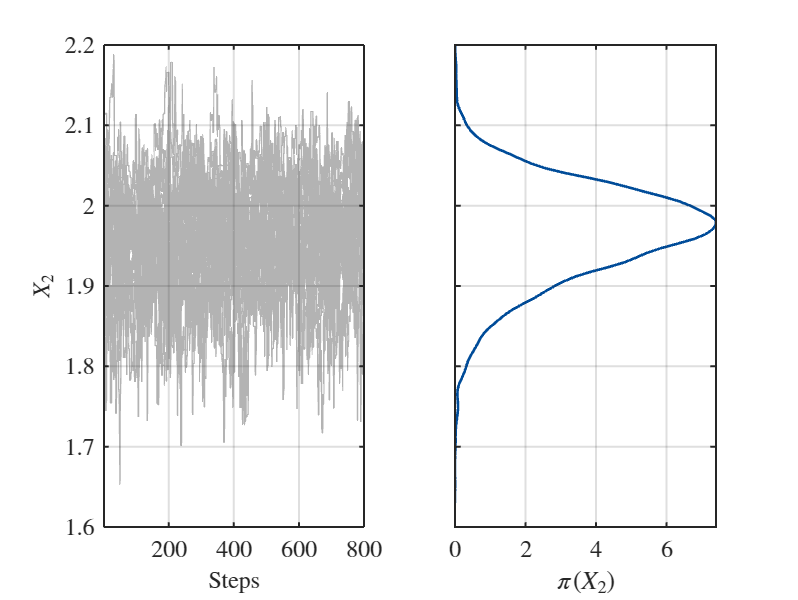


Finished AIES!


%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:09
   Number of sample points:                       2.40e+04

%------------------- Posterior Marginals
----------------------------------------------------------
| Parameter | Mean  | Std   | (0.05-0.95) Quant. | Type  |
----------------------------------------------------------
| X1        | 1.2   | 0.17  | ( 1 - 1.6)         | Model |
| X2        | 2     | 0.057 | (1.9 - 2.1)        | Model |
| Sigma2_1  | 0.047 | 0.028 | (0.0047 - 0.093)   | Model |
----------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | MAP     | Parameter Type |
----------------------------------------
| X1        | 1.1     | Mo

ans =     29     1


---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 2.216230e-05
---                 Calculation finished!                               ---


randomNoise = 2.6772

ans =      1     2


ans =         7200           2


ans =      1     2



Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

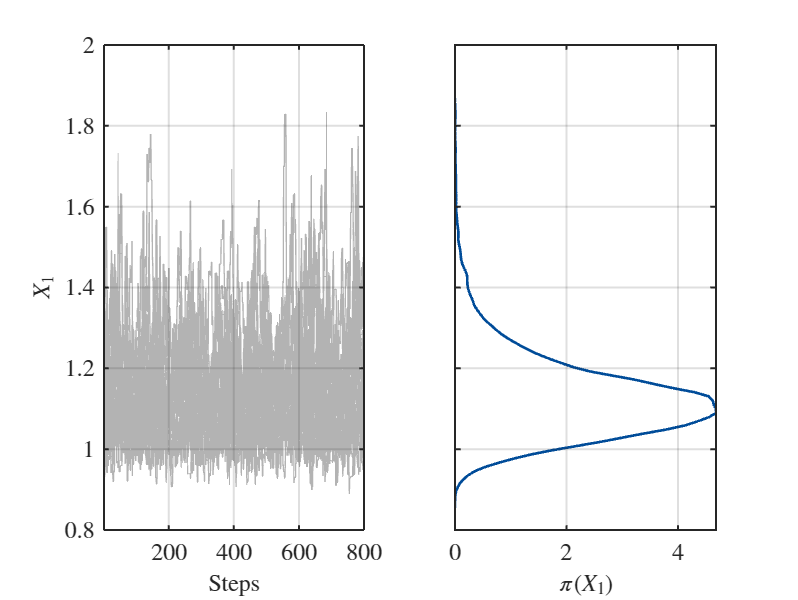

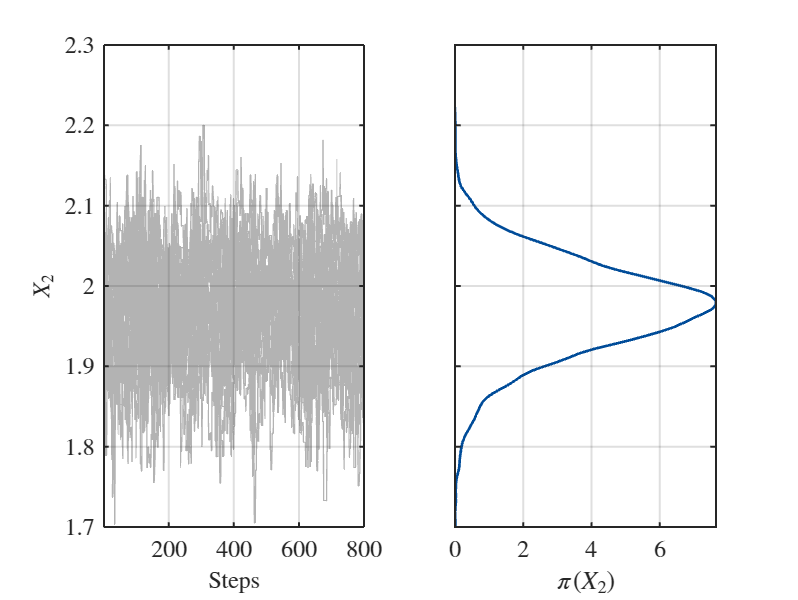


Finished AIES!


%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:20
   Number of sample points:                       2.40e+04

%------------------- Posterior Marginals
----------------------------------------------------------
| Parameter | Mean  | Std   | (0.05-0.95) Quant. | Type  |
----------------------------------------------------------
| X1        | 1.1   | 0.11  | (0.99 - 1.4)       | Model |
| X2        | 2     | 0.058 | (1.9 - 2.1)        | Model |
| Sigma2_1  | 0.055 | 0.034 | (0.0042 - 0.11)    | Model |
----------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | MAP     | Parameter Type |
----------------------------------------
| X1        | 1.1     | Mo

ans =     29     1


---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 2.354827e-05
---                 Calculation finished!                               ---


randomNoise = 0.7084

ans =      1     2


ans =         7200           2


ans =      1     2



Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

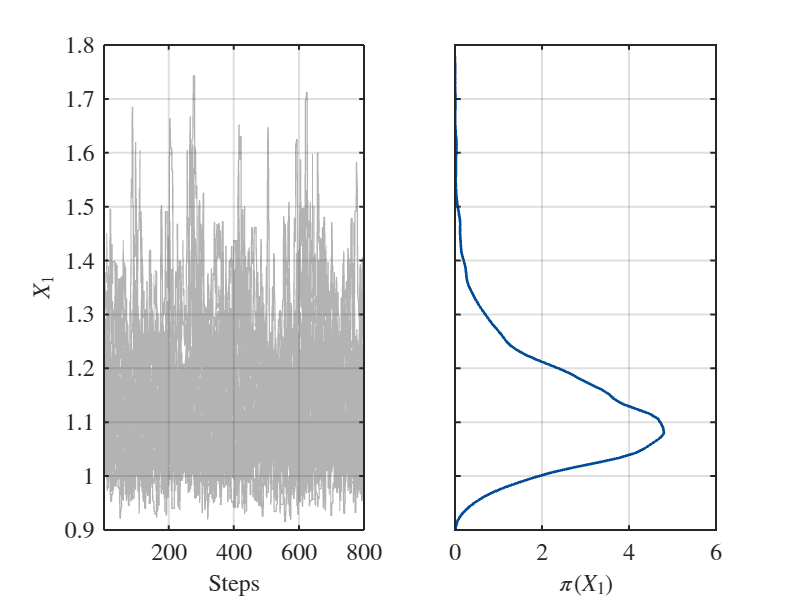

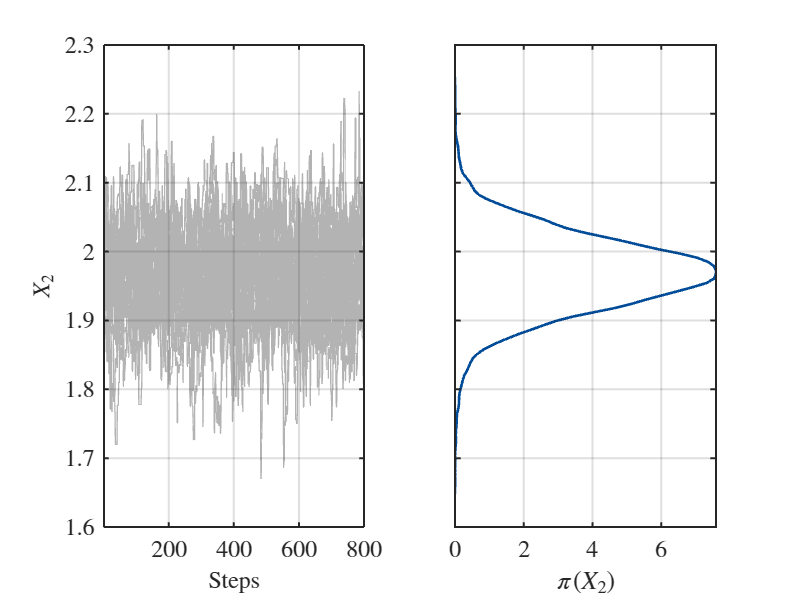


Finished AIES!


%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:19
   Number of sample points:                       2.40e+04

%------------------- Posterior Marginals
----------------------------------------------------------
| Parameter | Mean  | Std   | (0.05-0.95) Quant. | Type  |
----------------------------------------------------------
| X1        | 1.1   | 0.1   | (0.99 - 1.3)       | Model |
| X2        | 2     | 0.056 | (1.9 - 2.1)        | Model |
| Sigma2_1  | 0.038 | 0.026 | (0.0031 - 0.087)   | Model |
----------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | MAP     | Parameter Type |
----------------------------------------
| X1        | 1.1     | Mo

ans =     29     1


---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 5 and qNorm 0.75 for output variable 1
Final LOO error estimate: 2.303708e-05
---                 Calculation finished!                               ---


randomNoise = 0.1351

ans =      1     2


ans =         7200           2


ans =      1     2



Starting AIES...

|                              |   1.00%|#                             |   2.50%|#                             |   3.50%|##                            |   5.00%|##                            |   6.00%|##                            |   7.50%|###                           |   8.50%|###                           |  10.00%|###                           |  11.00%|####                          |  12.50%|####                          |  13.50%|#####                         |  15.00%|#####                         |  16.00%|#####                         |  17.50%|######                        |  18.50%|######                        |  20.00%|######                        |  21.00%|#######                       |  22.50%|#######                       |  23.50%|########                      |  25.00%|########                      |  26.00%|########                      |  27.50%|#########                     |  28.50%|#########                     |  30.00%|#########           

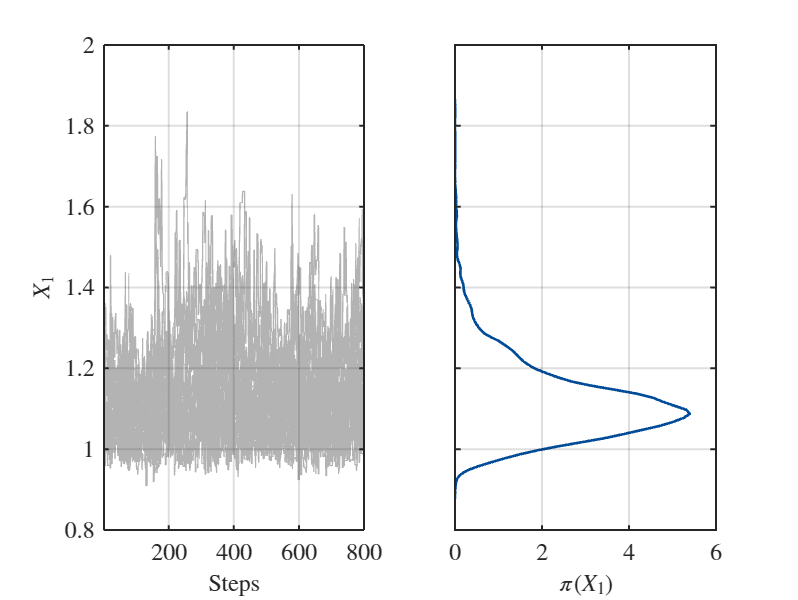

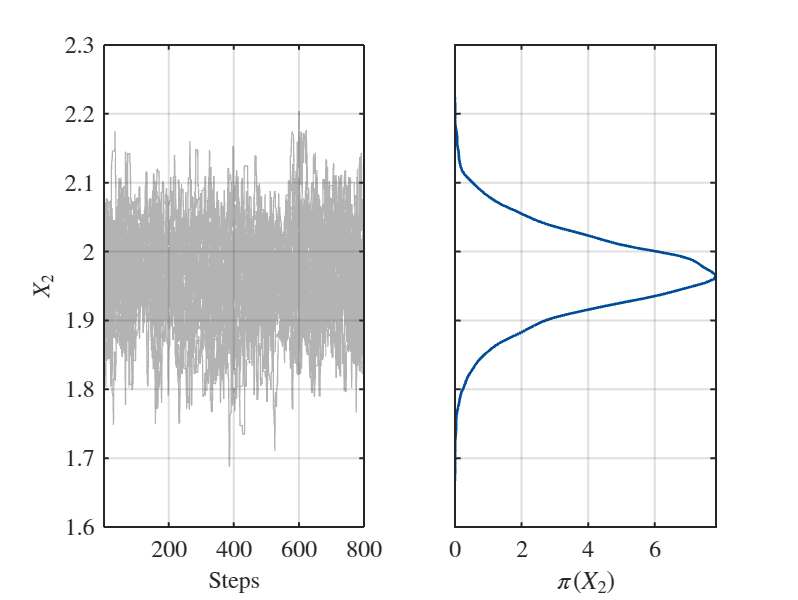


Finished AIES!


%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:01:22
   Number of sample points:                       2.40e+04

%------------------- Posterior Marginals
----------------------------------------------------------
| Parameter | Mean  | Std   | (0.05-0.95) Quant. | Type  |
----------------------------------------------------------
| X1        | 1.1   | 0.095 | (0.99 - 1.3)       | Model |
| X2        | 2     | 0.062 | (1.9 - 2.1)        | Model |
| Sigma2_1  | 0.037 | 0.025 | (0.0025 - 0.079)   | Model |
----------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | MAP     | Parameter Type |
----------------------------------------
| X1        | 1.1     | Mo

ans =         7200           2



uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7);

uq_print(BayesAnalysis);
% create cell to store the variables X1-X10
%%Note: dont use eval function (too redundent)
X_New_sample = {};
%extract samples from the posterior 
for i = 1: N_prior

    X_Postsample =  BayesAnalysis.Results.PostProc.PostSample(:,i,:);
    X_New_sample{i} = reshape(permute(X_Postsample, [2 1 3]), size(X_Postsample, 2), [])';

end
X_New_sample = cell2mat(X_New_sample);
% get mean and std of X1-X10 posterior
% create cell to store the mean and std of X1-X10
Mean_X = {};
Std_X = {};
for k = 1: N_prior
    Mean_X{k} = BayesAnalysis.Results.PostProc.Percentiles.Mean(:,k);
    Std_X{k} = BayesAnalysis.Results.PostProc.Percentiles.Var(:,k)^0.5;
end

% convert cell Mean_X/Std_X into matrix
Matrix_Mean_X = cell2mat(Mean_X)';
Matrix_Std_X = cell2mat(Std_X)';
Mean_Std_Sum{itotal} = [Matrix_Mean_X Matrix_Std_X];



%get the final posterior of last stage
if itotal==N_Stage
    % infer priors for X1-X10
    iOpts.Inference.Data = X_New_sample;
    size(X_New_sample)
    iOpts.Name = ['InputX' num2str(itotal+1)];
    InputHat = uq_createInput(iOpts);
    %Get prior sampling with excavation stage from distribution 
    Prior_sample = uq_getSample(N_Prior_Sample,'LHS'); 
    Prior_sample_Sum{itotal+1} = Prior_sample(:,1:N_prior);
end



end

# Plot figures

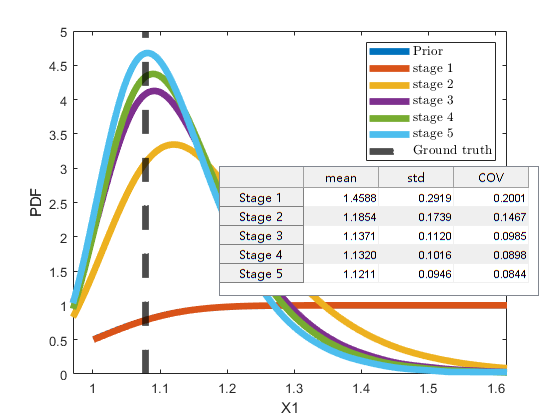

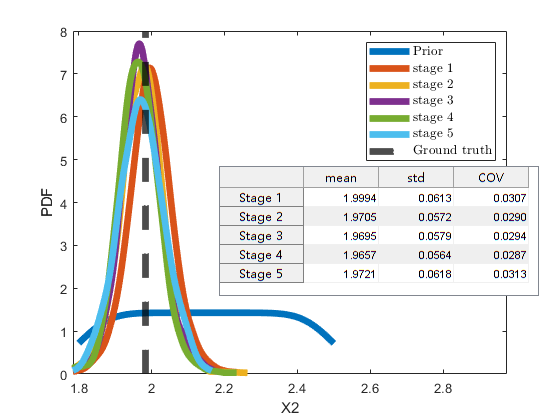

%GT: ground truth
GT_value = [1.078
1.983];
GT_name = ["X1" "X2" ];



close all


for k = 1:N_prior

    %get the mean/std/cov of the posterior
    
    mean_std_cov = [];
    for jj = 1:N_Stage
        
        mean_temp = Mean_Std_Sum{jj}(k,1);
        std_temp = Mean_Std_Sum{jj}(k,2);
        cov_temp = std_temp ./ mean_temp;
        mean_std_cov = [mean_std_cov; mean_temp std_temp cov_temp];
    
    end


    %create new plot
    figure;

    for i = 1:N_Stage+1
    
        %get the samples    
        X = Prior_sample_Sum{i}(:,k);
    
    
        %kernel density fitting    
        pdX = fitdist(X,'kernel');    
        peX = pdf(pdX,X);
        pdfX = sortrows([X peX],1);
    
        %plot pdf    
        eval(['h',num2str(i),'=','plot(pdfX(:,1),pdfX(:,2),''LineWidth'',5);']) ; 
               
        hold on;    

    end

    h7 = xline(GT_value(k),'--k','LineWidth',5); 


    %pbaspect([1 0.75 1]);
            
    lgd = legend([h1 h2 h3 h4 h5 h6 h7],{'Prior','stage 1', ...
                                                  'stage 2','stage 3', ...
                                                    'stage 4','stage 5', ...
                                                    'Ground truth'} ...
                                                    ,'FontSize',10,'Interpreter','latex'); 
    
    xlim([GT_value(k)*0.9 GT_value(k)*1.5])
    xlabel(['X' num2str(k)]);
    ylabel('PDF');
    hold on;
    uitable('Data', mean_std_cov, 'ColumnName', ...
             {'mean','std','COV'},  'RowName', {'Stage 1', 'Stage 2', 'Stage 3','Stage 4','Stage 5'} ...
             ,'Position', [220 125 320 130]);
    hold off;
    

end